# Activity 4: Modulation Transfer Function

#### Submitted by: Jonabel Eleanor B. Baldres

#### Applied Physics 167 THU

## Averaging the images

To do this, I used Automatic Image Stacking in OpenCV. Below is the averaged image of all the 10 photos taken. 

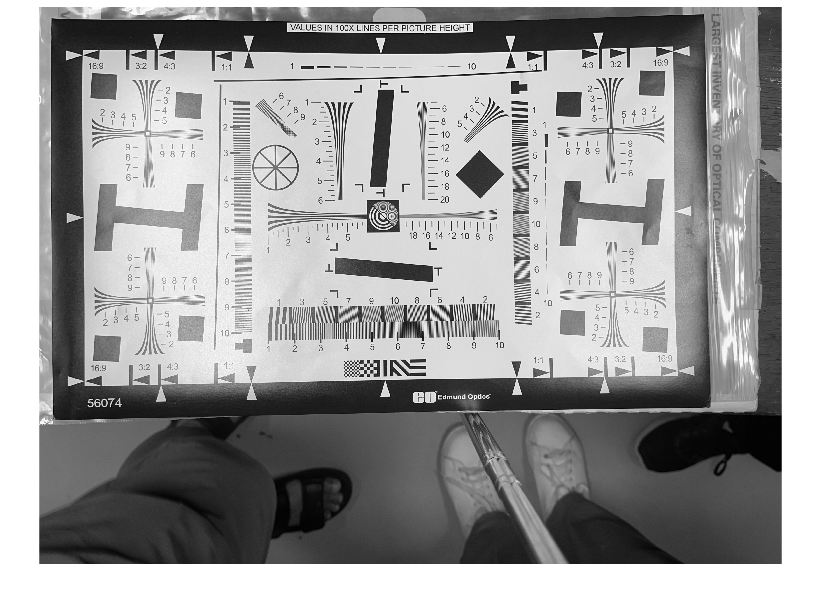

image = rgb2gray(uint8(double(imread('result_ECC.jpg'))));
figure;
imshow(image);


% Save the image
imwrite(image, 'grayscale_image.jpg');


## Creating line segments for getting the intensity profiles 

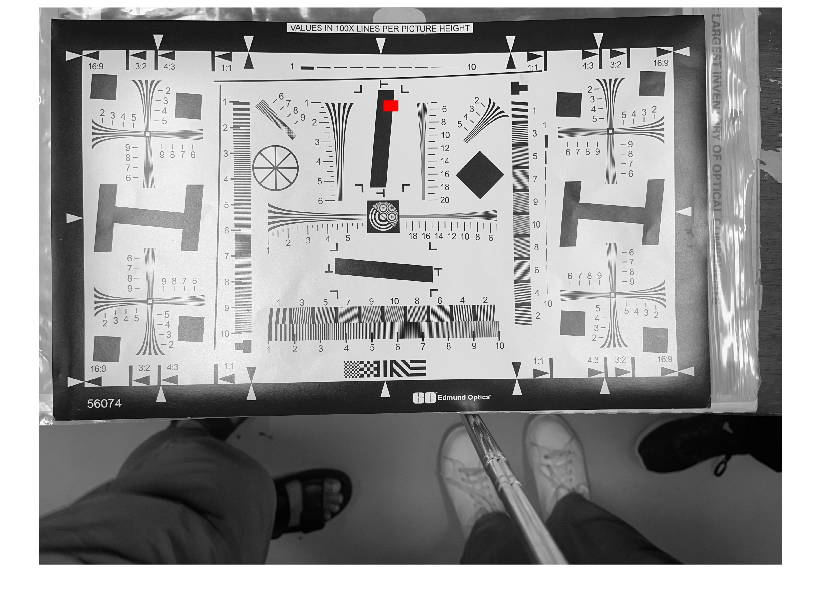

%Initializing the lineSegments matrix and defining fixed x-coordinates 
% x1 and x2 gives the first and last position of each line segment to get the length
x1 = 1870; 
x2 = 1950; 


%Specifying the number of line segments to utilize
numSegments = 50; 

% Initializing an empty array to store the line segments
lineSegments = [];

% Generating the line segments using a for loop
% Creating a new line segment and append it to the lineSegments array
imshow(image);
for i = 1:numSegments
    y =  510 + (i - 1); 
    lines = [x1, y, x2, y];
    lineSegments = [lineSegments; lines];
    
    
    hold on;
    plot([x1, x2], [y, y], 'r', 'LineWidth', 1); 
    hold off;
end

saveas(gcf, 'image_roi.png');

## Getting the intensity profiles, derivative of the intensity profiles, FFT, and abs(FFT) of each line segments 

% Storage of intensity profiles
profiles = cell(1, numSegments);


% Extracting intensity profiles for each line segment
for i = 1:numSegments
    x1 = lineSegments(i, 1);
    y1 = lineSegments(i, 2);
    x2 = lineSegments(i, 3);
    y2 = lineSegments(i, 4);
    
    profile = improfile(image, [x1, x2], [y1, y2]);
    profiles{i} = profile;
end

% Calculating the derivative, FFT, and abs(FFT) for each line segment
derivative_profiles = cell(1, numSegments);
fft_profiles = cell(1, numSegments);
abs_fft_profiles = cell(1, numSegments);

for i = 1:numSegments
    profile = profiles{i};
    
    % derivative using diff()
    derivative = diff(profile);
    derivative_profiles{i} = derivative;

    % FFT of the profile
    fft_result = fft(derivative);
    fft_profiles{i} = fft_result;

    % absolute FFT
    abs_fft = abs(fft_result);
    abs_fft_profiles{i} = abs_fft;
end


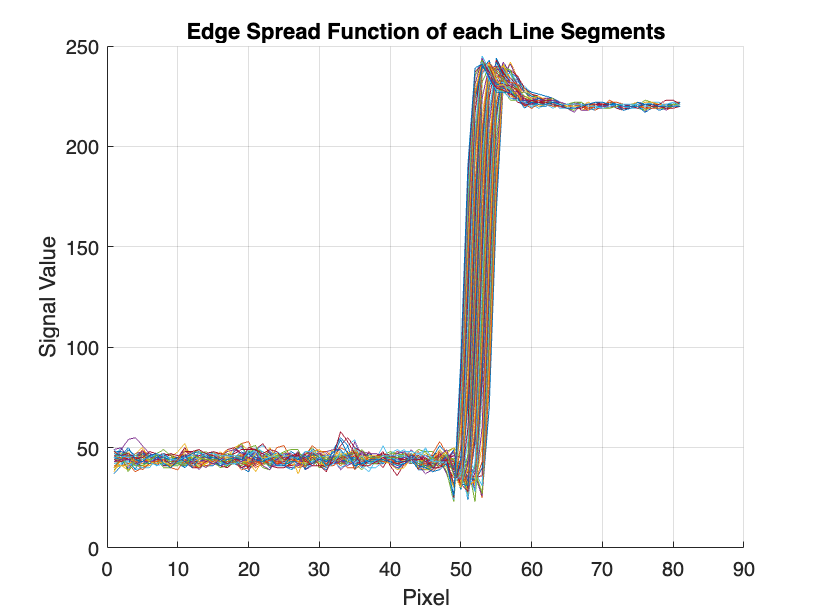

% Plotting all the intensity profiles

figure;
hold on;

for i = 1:numSegments
    plot(profiles{i});
end

hold off;
title('Edge Spread Function of each Line Segments');
xlabel('Pixel');
ylabel('Signal Value');
grid on;

% Save the plot
saveas(gcf, 'intensity_profiles.png');

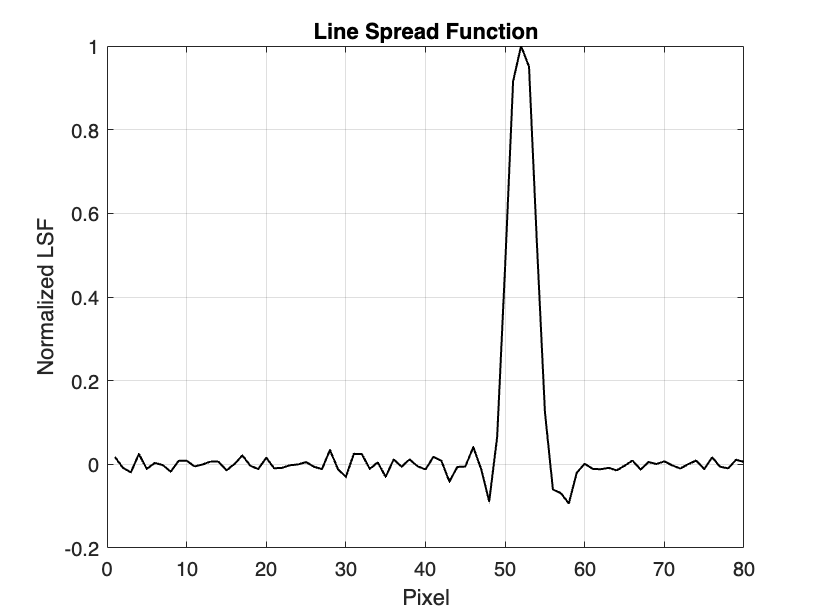

% Calculating the average line spread function of the profiles
average_derivative = zeros(size(derivative_profiles{1}));  

for i = 1:numSegments
    average_derivative = average_derivative + derivative_profiles{i};
end

average_derivative = average_derivative / numSegments;  

%Normalizing

average_derivative = average_derivative/ max(average_derivative); 

% Plotting the average derivative
figure;
plot(average_derivative, 'k ', LineWidth=1);
title('Line Spread Function');
xlabel('Pixel');
ylabel('Normalized LSF');
grid on;

% Save the plot
saveas(gcf, 'line_spread_function.png');

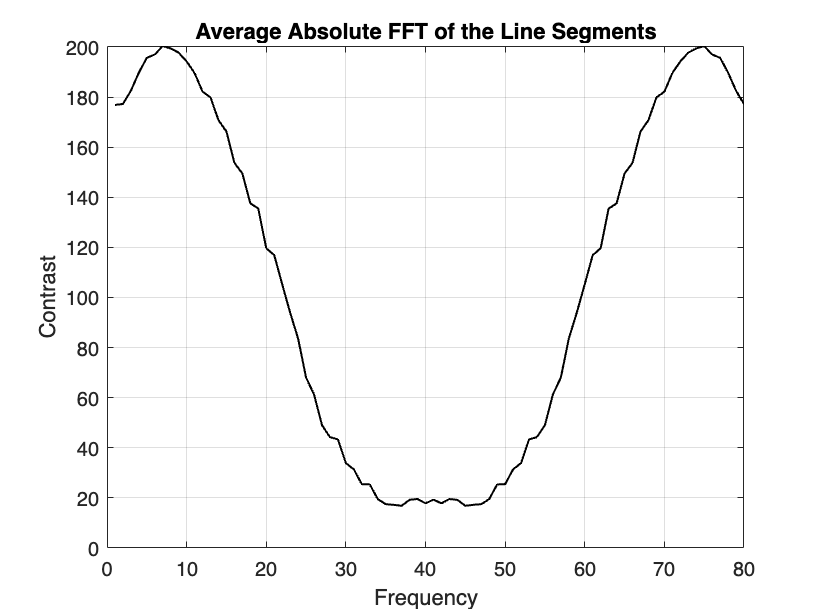


% Calculating the average of the absolute FFT profiles
average_abs_fft = zeros(size(abs_fft_profiles{1})); 

for i = 1:numSegments
    average_abs_fft = average_abs_fft + abs_fft_profiles{i};
end

%Getting the average absolute FFT
average_abs_fft = average_abs_fft / numSegments;  

% Plotting the average absolute FFT
figure;
plot(average_abs_fft, 'k' , LineWidth=1);
title('Average Absolute FFT of the Line Segments');
xlabel('Frequency');
ylabel('Contrast');
grid on;

% Save the plot
saveas(gcf, 'abs_fft.png');

## Getting the properly calibrated and normalized Modulation Transfer Function 

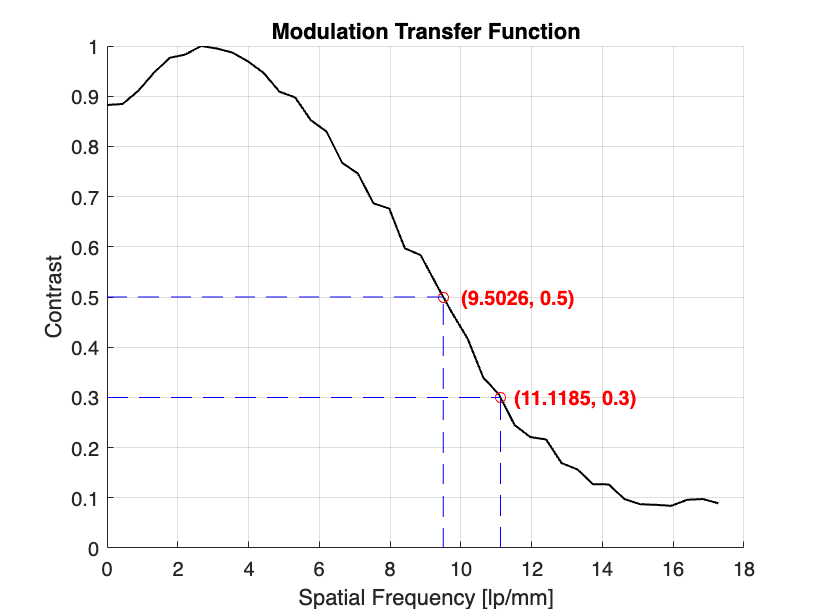

% Calculating and normalizing the MTF
MTF = average_abs_fft/max(average_abs_fft);
dx = 1/35; 
N = length(MTF);
x = 0:dx:(N-1)*dx; 
Fmax = 1/(2*dx);
df = 1/((N-1)*dx);
K = round(N/2); 
f = 0:df:Fmax;


% Defining the spatial frequency and contrast values
spatial_frequency_1 = 9.5026;
contrast1 = 0.5;
spatial_frequency_2 = 11.1185;
contrast2 = 0.3;


% Plot the MTF
figure;
hold on; 
plot(f, MTF(1:K), 'k', LineWidth=1);
plot(spatial_frequency_1, contrast1, 'ro', 'MarkerSize', 5); 
line([0, spatial_frequency_1], [contrast1, contrast1], 'Color', 'b', 'LineStyle', '--');
line([spatial_frequency_1, spatial_frequency_1], [0, contrast1], 'Color', 'b',  'LineStyle', '--');
plot(spatial_frequency_2, contrast2, 'ro', 'MarkerSize', 5); 
line([0, spatial_frequency_2], [contrast2, contrast2], 'Color', 'b', 'LineStyle', '--');
line([spatial_frequency_2, spatial_frequency_2], [0, contrast2], 'Color', 'b',  'LineStyle', '--');
xlabel('Spatial Frequency [lp/mm]');
ylabel('Contrast');
title('Modulation Transfer Function');
text(10, 0.5, '(9.5026, 0.5)', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'red');
text(11.5, 0.3, '(11.1185, 0.3)', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'red');
grid on;
ylim([0 1]);

% Save the plot
saveas(gcf, 'MTF.png');